# Bedform evolution

In this script, we find an analytical solution to Exner equation assuming a constant water sruface level (i.e. the rig-lid assumption), which is a good approximation for relatively small bedforms in steady flow and small Froude numbers. We will use this to show how **an initially symmetrical bedform evolves into the well-known form presenting a steep downstream face and mild slope upstream, while migrating dowsntream.** 

Run the code for several values of the input parameters and analyse their effect.

## Input data (set up)

%Sergio Maldonado
clear variables
close all
clc

First, we set parameters that will define the initial bedform:

xi = 300;           % bedform starts at this position (m)
xf = 500;           % bedform ends at this position (m)
x0 = xi:1:xf;       % building the x-coordinates vector
H = 1;              % initial height of bedform (m)
por = 0.64;         % bed porosity

With this information, we build our initial bedform profile according to the formula:

zb = H.*(sin(pi.*(x0 - xi)./(xf - xi))).^2;

Now, our hydraulic parameters:

eta = 10;           % water surface level from the bed (m)
q0 = 10;             % constant discharge per unit width (m^2/s)


Next, bedload is computed as $q_b = A U^m$, so we need values for:

A = 0.01;            % empirical constant
m = 3;              % also empirical, but typically = 3


Finally, we want to know the final state of the bedform after *t* seconds:

t = 10800;           % 'simulation' time (s)

## Solution

The solution to this problem is analytical and is based on the Method of Characteristics, as described in the paper by Huang et al. (2008) 'One-dimensional modelling of fluvial bed morphodynamics' *Journal of Hydraulic Research*. 

% Solution based on Huang et al. (2008)

Xch = eta*(1 - zb./eta).^(-m - 1);
T = ( (1 - por).*eta.^(m+2) )./(A.*m.*q0.^m);
x = x0 + Xch.*t./T;


We finally plot our initial and final bedform profiles.

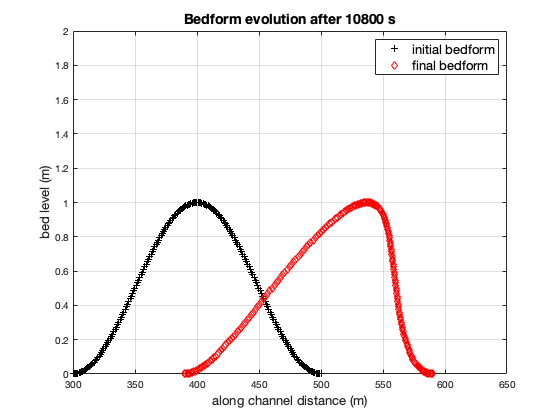

plot(x0,zb,'+k')
hold on
plot(x,zb,'dr')
xlim([300 650])
ylim([0 2.0])
xlabel('along channel distance (m)','FontSize',13)
ylabel('bed level (m)','FontSize',13)
lgd = legend('initial bedform','final bedform');
lgd.FontSize = 13;
title(['Bedform evolution after ',num2str(t), ' s'],'FontSize',14)
grid on


disp(['Upstream water depth is: ',num2str(eta),' m'])

Upstream water depth is: 10 m


disp(['Steady discharge is: ',num2str(q0),' m^2/s'])

Steady discharge is: 10 m^2/s


disp(['Froude number is: ',num2str(q0/eta/sqrt(eta*9.81))])

Froude number is: 0.10096


(Remember, the rigid-lid assumption is only valid for small values of the Froude number.)